clc, clearvars;
dsRoad = imageDatastore("/home/kheyal/Documents/Computer-Vision/ComputerVisionData/MathWorks Images/Roadside Ground Cover", "IncludeSubfolders",true, "LabelSource","foldernames");
categories(dsRoad.Labels)

ans = 2×1 cell array
    {'No Snow'}
    {'Snow'   }


[dsTrain, dsTest] = splitEachLabel(dsRoad, .85, "randomized");
numSnowImages = sum(dsTrain.Labels == "Snow")

numSnowImages = 85

saturationMean = [];
saturationStd = [];
imgName = [];

while hasdata(dsTrain)

    [img, info] = read(dsTrain);
    img = im2double(img);
    img = rgb2hsv(img);
    
    saturation = img(:, :, 2);
    saturationMean = [saturationMean; mean(saturation(:))];
    saturationStd = [saturationStd; std(saturation(:))];
    
    [~, name, ext] = fileparts(info.Filename);
    imgName = [imgName; string(name) + string(ext)];

end

label = categorical(dsTrain.Labels);
roadImageTable = table(label, imgName, saturationMean, saturationStd)

roadImageTable = 170×4 table
     label           imgName          saturationMean    saturationStd
    _______    ___________________    ______________    _____________

    No Snow    "RoadsideA_1.jpg"          0.3806           0.23021   
    No Snow    "RoadsideA_10.jpg"        0.41786           0.13897   
    No Snow    "RoadsideA_100.jpg"       0.28212           0.20909   
    No Snow    "RoadsideA_11.jpg"        0.47767           0.19187   
    No Snow    "RoadsideA_12.jpg"         0.4751           0.18522   
    No Snow    "RoadsideA_13.jpg"        0.44419            0.1497   
    No Snow    "RoadsideA_14.jpg"        0.58536           0.22019   
    No Snow    "RoadsideA_15.jpg"        0.46897           0.20315   
    No Snow    "RoadsideA_17.jpg"        0.29202           0.17761   
    No Snow    "RoadsideA_18.jpg"        0.48444           0.187

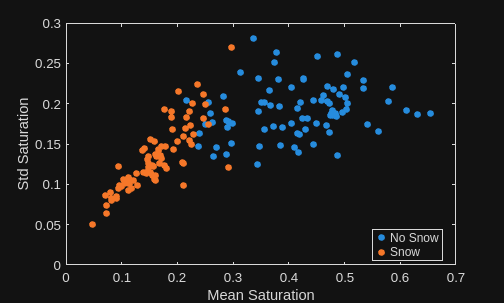

gscatter(roadImageTable.saturationMean, roadImageTable.saturationStd, roadImageTable.label);
xlabel("Mean Saturation");
ylabel("Std Saturation");